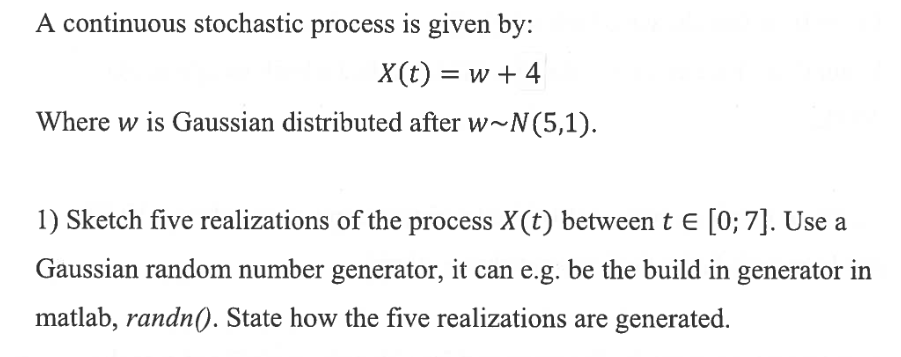

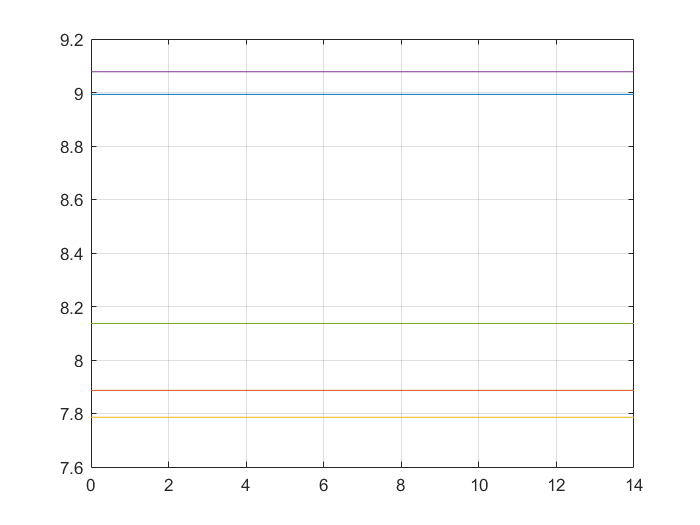

%(randn(1,5)*sigma)+mu
sigma = 1;
mu = 5;
w=(randn(1,5)*sigma)+mu;%%Create 5 random values with randn
%offset with 5 cause of the mu value, the sigma value is multiplied to every random generated nummer to give it a variance.
%the only reason we can use randn is because the gaussian distribution is a normaldistributtion

t=0:7;%%t is between 0 and 7. Important to know that we can't with 100% certainty say that 0-7 is the same as 7-14. therefore it's defined...Also, they are trying to confuse you.

x5=w(5)+4;%One possible realization of the process of X(t)
x4=w(4)+4;
x3=w(3)+4;
x2=w(2)+4;
x1=w(1)+4;

plot(t,ones(1,length(t))*x5)
grid
hold on
plot(t,ones(1,length(t))*x4)
plot(t,ones(1,length(t))*x3)
plot(t,ones(1,length(t))*x2)
plot(t,ones(1,length(t))*x1)

If the code is run multiple times it's shown that the realizations change. 

This is due to an infinite amount of realizations within an interval.

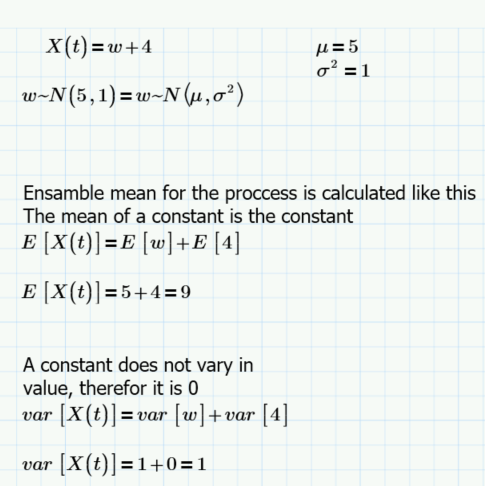

meanOfRealization = mean(x3)+ mean(4)

meanOfRealization = 11.7859


varOfRealization = var(x3)+var(4)

varOfRealization = 0

The variance of one realization doesn't say much because it will always be 0.

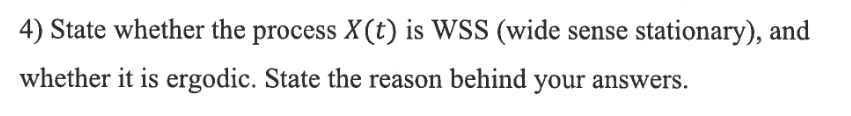

The ensamble variance and the ensamble mean does not have an aspect of time in the formula, etc. w+4*t or w+4/t. That means that the process X(t) is

independent of time and  **is therefore Wide State Stationary**. In addition if you double the time interval the ensamble variance  and ensamble mean stays the same.

The time average is not equal for all the realizations and is therefor not ergodic.